%Controllability and Observability

clc;
A=[0 1 0;0 0 1;0 -5 -6];
B=[0;0;1];
C=[1 0 0];
D=[0];
SYS=ss(A,B,C,D);
%(I)Checking controllability and observability
Cr=det(ctrb(A,B));
O=det(obsv(SYS));
if Cr~=0
    disp("The System is Controllable")
else
    disp("The System is not Controllable")
end

The System is Controllable


if O~=0
    disp("The System is Observable")
else
    disp("The System is not Observable")
end

The System is Observable


%(II)Determine the state-feedback gain constants
p=[-2+4*1i,-2-4*1i,-10];
k=acker(A,B,p);
k1=[1 0 0]*k'

k1 = 200

k2=[0 1 0]*k'

k2 = 55

k3=[0 0 1]*k'

k3 = 8

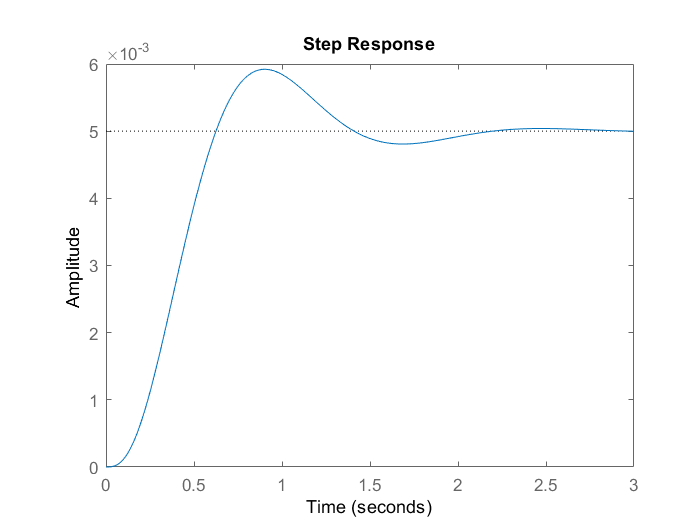

%(III) unit-step response and y(t) versus t curve
A_new=A-B*k;
SYS_new=ss(A_new,B,C,D);
[num,den]=ss2tf(A_new,B,C,D);
F=tf(num,den);
syms s;
Z=1/(s^3+14*s^2+60*s+200);
G=ilaplace(Z);
step(SYS_new)

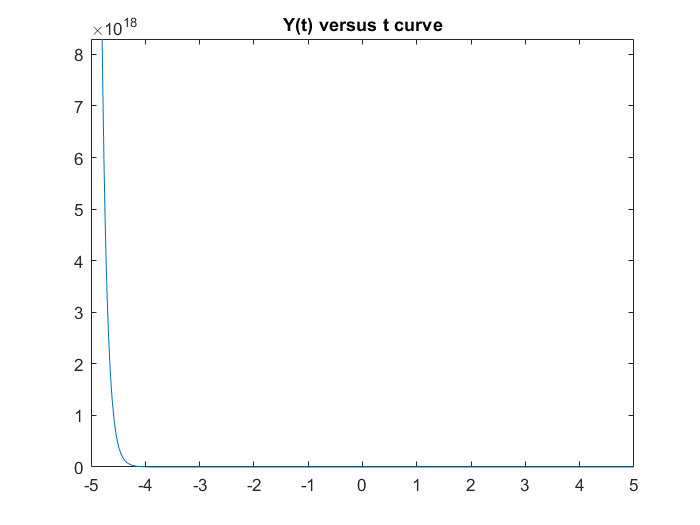

fplot(G)
title('Y(t) versus t curve')